# Fixpunktiteration

Wir betrachten ein Fixpunktproblem $\Phi(x)=x$, mit den Funktionen:

(1)   $\Phi(x)=x^6-1$

(2)   $\Phi(x)=(x+1)^{\frac16}$

(3)   $\Phi(x)=\cos(x)$

(4)   $\Phi(x)=1-e^{-x}$

(5)   $\Phi(x)=\frac12(x+\frac{2}{x})$

Für (1) und (2) ist die Aufgabe $\Phi(x)=x$ äquivalent zum Nullstellenproblem $x^6-x-1=0$ (siehe Buch).

In Beispiel (4) gilt $\Phi'(x^\ast)=1$ und in Beispiel (5) gilt $\Phi'(x^\ast)=0$.

In der MATLAB-Funktion TCM_fixed_point   wird die Fixpunktiteration zur Lösung der Fixpunktaufgabe verwendet.  

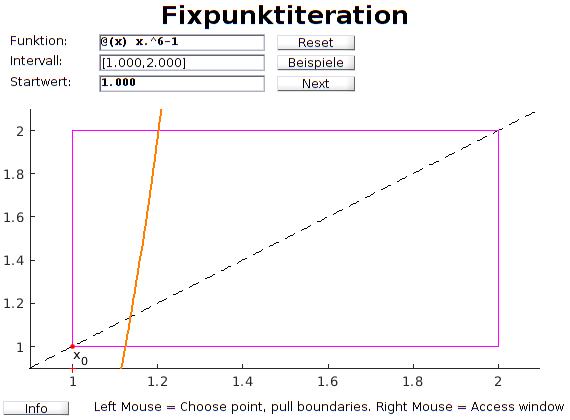

TCM_fixed_point

Die gezeigte Fehlerschätzung (``Fehlerschaetz'')  basiert auf der im Buch behandelten Methode:


$$x^\ast-x_k \approx \frac{A_k}{1-A_k}(x_k-x_{k-1}), \quad A_k:=\frac{x_k-x_{k-1}}{x_{k-1}-x_{k-2}}.$$


Diese Methode ist nur in den Fällen sinnvoll, wenn die Konvergenz der Folge $(x_k)_{k\geq0}$ **linear** ist. Dann gilt $\lim_{k \to \infty} A_k=A =\Phi'(x^\ast)\in (0,1)$.

# Aktivität:

Drücken Sie "Run" bzw. F5, um die Demo zu starten.Variieren Sie den Startwert $x_0$ und untersuchen Sie die Beispiele (1)-(5) hinsichtlich (lokaler) Konvergenz bzw. Divergenz.

Unterstehendes MATLAB-Program **TCM_fixed_point** wurde an der Uni-Stuttgart im Rahmen des Projektes ``Teaching Calculus mit MATLAB'' entwickelt, siehe https://pnp.mathematik.uni-stuttgart.de/imng/TCM/

function TCM_fixed_point

% TCM_FIXED_POINT illustrates a fixed point iteration x <- f(x) based on
% Banach's famous theorem
%
%   To investigate own examples, insert a function, an interval, and an initial point
%   in the corresponding fields.
%
%   TCM_FIXED_POINT is part of the <a href="http://www2.imng.uni-stuttgart.de/LstNumGeoMod/TCM/">TCM</a> project.
%   Related course materials can be found at <a href="http://www.mathematics-online.org/inhalt/aussage/aussage681">Mathematics Online</a>.

% Authors: Jörg Hörner
% Modified by Arnold Reusken 

% Initialize data
TCM_Data.move = 0;
TCM_Data.fun = @(x) cos(x);  
TCM_Data.funstring = '@(x) cos(x)';  
TCM_Data.point = NaN;
TCM_Data.rate = NaN;
TCM_Data.interval = [-0.5 1.5];
TCM_Data.error= NaN;

% Do not delete these Variables
TCM_Data.plot_window = repmat(TCM_Data.interval,1,2);
TCM_Data.LmbMenuString = '';
TCM_Data.examples = {'(1) Divergent x^6 - x - 1 = 0', '(2) Konvergent x^6 - x - 1 = 0', ...
        '(3) Cosinus', '(4) Grenzfall L=1', '(5) Quadratische Konvergenz'};

% Layout:
% ---------------------------------------
% |               Title                 |
% | ------------ --------- ------------ |
% | | Settings | |Buttons| | Feedback | |
% | ------------ --------- ------------ |
% | ----------------------------------- |
% | |           Axis (Plot)           | |
% | ----------------------------------- |
% | Info-Button         Hint            |
% ---------------------------------------
% Initialize Layout:
TCM_UI.TitleHeightMin = 10;        % minimal height of the title
TCM_UI.TitleHeightMax = 32;        % maximal height of the title
TCM_UI.HintHeightMin = 8;          % minimal height of the hint
TCM_UI.HintHeightMax = 15;         % maximal height of the hint
TCM_UI.SettingsHeightMin = 40;     % minimal height of the feedback, buttons and 
                                   % setting panel
TCM_UI.SettingsHeightMax = 70;     % maximal height of the feedback, buttons and 
                                   % setting panel
TCM_UI.SettingsRatio = 4.5;          % aspect ratio of the settings  
                                   % (increase if more settings needed)
TCM_UI.ButtonsRatio = 1.4;         % aspect ratio of the Buttons panel
TCM_UI.FeedbackRatio = 3.4;        % aspect ratio of the feedback
TCM_UI.AxisHeightTarget = 0.73;    % desired fraction of figure 
                                   % used for the plot
TCM_UI.InfoPortion = 1/8;          % Portion of the Info Button in the last  
                                   % line
TCM_UI.Title = 'Fixpunktiteration';
TCM_UI.mono = get(0,'FixedWidthFontName');
% Strings for generating the information window
TCM_UI.Author = 'J. Hörner';
TCM_UI.Date = '30.09.2016';
TCM_UI.Web = 'http://www.mathematics-online.org/inhalt/aussage/aussage681';
      
CreateUI();

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% UI-Elements in Settings %%%%%%%%%%%%%%%%%%%%
% Text for function
TCM_UI.funtext = uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontUnits','normalized','FontSize',0.67,...
        'HorizontalAlignment','left', ...
	'Position',[.01,.70,.35,.30],...
	'String','Funktion:',...
	'Style','text');

% Input for function
TCM_UI.funinput=uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontWeight','bold',...
        'FontUnits','normalized','FontSize',0.65,'FontName',TCM_UI.mono,...
        'HorizontalAlignment','left', ...
	'Position',[.35,.70,.63,.30],...
	'String','',...
	'Style','edit',...
	'Callback',@function_update);

% Text for interval
TCM_UI.intervaltext=uicontrol('Units','normalized','Parent',TCM_UI.settingspanel,...
        'BackgroundColor',get(gcf,'Color'), ...
        'HorizontalAlignment','left', ...
        'FontUnits','normalized','FontSize',0.7,...
	'Position',[.01,.35,.35,.3],...
	'String',sprintf('Intervall:'),...
	'Style','text');

% Input for interval
TCM_UI.intervalinput=uicontrol('Units','normalized','Parent',TCM_UI.settingspanel,...
        'BackgroundColor',get(gcf,'Color'), ...
        'HorizontalAlignment','left', ...
        'FontUnits','normalized','FontSize',0.7,...
	'Position',[.35,.35,.63,.3],...
	'String','[NaN,NaN]',...
	'Style','edit',...
    'Callback',@interval_update);

% Text for point
TCM_UI.pointtext = uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontUnits','normalized','FontSize',0.67,...
        'HorizontalAlignment','left', ...
	'Position',[.01,.0,.35,.30],...
	'String','Startwert:',...
	'Style','text');

% Input for point
TCM_UI.pointinput=uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontWeight','bold',...
        'FontUnits','normalized','FontSize',0.65,'FontName',TCM_UI.mono,...
        'HorizontalAlignment','left', ...
	'Position',[.35,.0,.63,.30],...
	'String','NaN',...
	'Style','edit','Callback',@new_point);

%%%%%%%%%%%%%%%%%%%%%%%%% UI-Elements in Buttons Panel %%%%%%%%%%%%%%%%%%%%
% Reset button
TCM_UI.reset=uicontrol('Units','normalized','Parent',TCM_UI.buttonspanel, ...
	'BackgroundColor',get(gcf,'Color'), ...
	'String','Reset', ...
    'FontUnits','normalized','FontSize',0.7,...
	'Position',[.01,.70,.98,.30], ...
	'Callback',@reset,...
	'Style','pushbutton');

% Example button
TCM_UI.examples=uicontrol('Units','normalized','Parent',TCM_UI.buttonspanel, ...
	'BackgroundColor',get(gcf,'Color'), ...
	'String','Beispiele', ...
    'FontUnits','normalized','FontSize',0.7,...
	'Position',[.01,.35,.98,.30], 'Callback',@OpenExampleMenu,...
	'Style','pushbutton');

% Next button
TCM_UI.next=uicontrol('Units','normalized','Parent',TCM_UI.buttonspanel, ...
	'BackgroundColor',get(gcf,'Color'), ...
	'String','Next', ...
    'FontUnits','normalized','FontSize',0.7,...
	'Position',[.01,.0,.98,.30], ...
	'Callback',@nextstep,...
	'Style','pushbutton');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% UI-Elements in Feedback %%%%%%%%%%%%%%%%%%%%

% Current point
TCM_UI.current_point=uicontrol('Units','normalized','Parent',TCM_UI.feedbackpanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'HorizontalAlignment','left', ...
        'FontUnits','normalized','FontSize',0.7,'FontWeight','bold', ...
	'Position',[.01,.7,.98,.3],...
	'String',sprintf('Neuer Wert: %12.3e',TCM_Data.point(end)),...
	'Style','text',...
        'visible','off');

% Rate
TCM_UI.rate=uicontrol('Units','normalized','Parent',TCM_UI.feedbackpanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'HorizontalAlignment','left', ...
        'FontUnits','normalized','FontSize',0.7,...
	'Position',[.01,.35,.98,.3],...
	'String',sprintf('Faktor: %12.3e',TCM_Data.rate),...
	'Style','text',...
        'visible','off');

% Convergence
TCM_UI.error=uicontrol('Units','normalized','Parent',TCM_UI.feedbackpanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'HorizontalAlignment','left', ...
        'FontUnits','normalized','FontSize',0.7,'FontWeight','bold', ...
	'Position',[.01,.0,.98,.3],...
	'String',sprintf('Fehler: %12.3e',TCM_Data.error),...
	'Style','text',...
        'visible','off');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% UI-Elements in Axis %%%%%%%%%%%%%%%%%%%%%%%%
TCM_UI.ax=axes('Position',[.05,.1,.9,.85],'Parent',TCM_UI.axispanel);
axis(TCM_UI.ax,'equal');
TCM_UI.modification = uicontextmenu('Callback',@reset_zoom_limits); 
TCM_UI.mpan = uimenu('Parent',TCM_UI.modification,'Label','Enable pan',...
        'Callback',@axis_context);
TCM_UI.mzoomi = uimenu('Parent',TCM_UI.modification,'Label','Enable zoom in',...
    'Callback',@axis_context); 
TCM_UI.mzoomo = uimenu('Parent',TCM_UI.modification,'Label','Enable zoom out',...
        'Callback',@axis_context); 
TCM_UI.ax.UIContextMenu = TCM_UI.modification;

% functions for smoothless zooming and panning
panfun = pan(TCM_UI.fig);
panfun.UIContextMenu = TCM_UI.modification;
set(panfun,'ActionPostCallback',@pan_modify);
zoomfun = zoom(TCM_UI.fig);
zoomfun.UIContextMenu = TCM_UI.modification; 
set(zoomfun,'ActionPostCallback',@zoom_modify);
set(zoomfun,'ButtonDownFilter',@set_zoom_limits);
set(zoomfun,'RightClickAction','PostContextMenu');
set(findall(TCM_UI.fig,'tag','Exploration.Pan'),'enable','off');
set(findall(TCM_UI.fig,'tag','Exploration.ZoomOut'),'enable','off');
set(findall(TCM_UI.fig,'tag','Exploration.ZoomIn'),'enable','off');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Start the program %%%%%%%%%%%%%%%%%%%%%%%%%%
changeexample(1);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%% Callback functions %%%%%%%%%%%%%%%%%%%%%%%%%%%
% new function input
function function_update(varargin)
TCM_Data.funstring = get(TCM_UI.funinput,'String');
TCM_Data.fun = eval(TCM_Data.funstring);

fixfun = @(x) TCM_Data.fun(x)-x;
options = optimset('Display','off');
[fix,~,exit] = fzero(fixfun,1e-3,options);

if exit < 1
    reset;
else
    inter = round(2*[fix-1,fix+1])/2;
    set(TCM_UI.intervalinput,'String',['[',num2str(inter),']']);
    interval_update;
end
end

function interval_update(varargin)
int = eval(get(TCM_UI.intervalinput,'String'));
TCM_Data.interval = int;
h = int(2)-int(1); int = int +[-h/10 h/10];
TCM_Data.plot_window = [int int];

reset;
end

function new_point(varargin)
% read the new point and call the myplot function to refresh the plot
TCM_Data.point = str2double(get(TCM_UI.pointinput,'String'));

myplot;
end

function reset(varargin)
% Restore default variables
TCM_Data.point = NaN;
TCM_Data.rate = NaN;
TCM_Data.error = [];

window_disable.Label = 'Disable pan';
axis_context(window_disable);

myplot;
end

% button next pressed
function nextstep(varargin)
% Next iterate
if ~isnan(TCM_Data.point)
   TCM_Data.point = [TCM_Data.point; TCM_Data.fun(TCM_Data.point(end))];
end

myplot;
end

% mouse button pressed 
function myDownfct(varargin)
p = getClickPosition(TCM_UI.ax);
if isnan(p)
    return
elseif strcmp(get(gcf,'SelectionType'),'normal')
    for i=1:2
        dist(i) = abs(p(1)-TCM_Data.interval(i));
    end
    [dist,j] = min(dist);
    if dist < 0.05*diff(TCM_Data.plot_window([1 2]))
        if (p(2) < TCM_Data.interval(2) && p(2) > TCM_Data.interval(1))            
            TCM_Data.interval(j) = p(1);          
            TCM_Data.move = j;
            myplot;
            return
        end
    end        
    TCM_Data.point = p(1);
    set(TCM_UI.pointinput,'String',num2str(TCM_Data.point));
    myplot;
end
end

function myUpfct(varargin)
TCM_Data.move = 0.5;
myplot;
TCM_Data.move = 0;
end

function myMovefct(varargin)
if TCM_Data.move > 0.5
    p = getClickPosition(TCM_UI.ax);
    if(isnan(p))
       return;
    end
    TCM_Data.interval(TCM_Data.move) = p(1);
    myplot;
end
end

function p = getClickPosition(myaxes)
x = get(myaxes,'xlim');
y = get(myaxes,'ylim');
newpoint=get(myaxes,'CurrentPoint');
if (newpoint(1) < x(1) || newpoint(1) > x(2) || ...
    newpoint(3) < y(1) || newpoint(3) > y(2))
    p = NaN;
else
    p = newpoint([1 3]);
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% kernel functions %%%%%%%%%%%%%%%%%%%%%%%%%%%
function myplot
subplot(TCM_UI.ax)
cla reset; hold on

h = TCM_Data.plot_window(2) - TCM_Data.plot_window(1);
x = linspace(TCM_Data.plot_window(1)-h,TCM_Data.plot_window(2)+h,1000);
plot([x(1) x(end)],[0 0],'black');
fx = TCM_Data.fun(x);
plot(x,fx,'-b','linewidth',2);
plot(x,x,'--black');
fill(TCM_Data.interval([1 2 2 1 1]), TCM_Data.interval([1 1 2 2 1]),'white','EdgeColor','m','FaceAlpha',0);

delta = x(2)-x(1);
dfx = diff(fx)/delta;
ind = find(abs(dfx)<1);
fx(ind) = NaN;
fx(ind+1) = NaN;
plot(x,fx,'-','linewidth',2,'color',[1 .5 0]);

% f(I) subset I
xi = linspace(TCM_Data.interval(1),TCM_Data.interval(2),1000);
fxi = TCM_Data.fun(xi);
delta = xi(2)-xi(1);
dfxi = diff(fxi)/delta;

ind = fxi < xi(end) & fxi > xi(1);
fxi(ind) = NaN;

set(TCM_UI.current_point,'visible','off');
set(TCM_UI.rate,'visible','off');
set(TCM_UI.error,'visible','off');



xlim([TCM_Data.plot_window(1) TCM_Data.plot_window(2)]);
ylim([TCM_Data.plot_window(3) TCM_Data.plot_window(4)]);

if TCM_Data.plot_window(3) < TCM_Data.interval(1)
    if sign(TCM_Data.plot_window(3)) < 1
        h_axis = 0;
    else
        h_axis = TCM_Data.plot_window(3);
    end
else
    h_axis = max(0,TCM_Data.plot_window(3));
end

% Plot the initial point and the points generated by the iteration 
% including a visualization of the fixed point recursion
if ~isnan(TCM_Data.point)
    plot(TCM_Data.point(1),h_axis,'+r','MarkerSize',5);
    plot(TCM_Data.point(1),TCM_Data.point(1),'.r','MarkerSize',10);
    text(TCM_Data.point(1),h_axis,'x_0','VerticalAlignment','Bottom','Clipping','on');
    if length(TCM_Data.point)>1
	set(TCM_UI.current_point,'visible','on');
	set(TCM_UI.error,'visible','on');
      if length(TCM_Data.point)>3
        set(TCM_UI.rate,'visible','on');
      end
       for k=2:length(TCM_Data.point)-1;
           plot(TCM_Data.point(k),h_axis,'+r','MarkerSize',5);
           plot(TCM_Data.point([k-1,k-1,k]),TCM_Data.point([k-1,k,k]),'-black');
           plot(TCM_Data.point(k),TCM_Data.point(k),'.r','MarkerSize',10);
       end
       npts = 10; 
       k = length(TCM_Data.point)-1;
       x = linspace(TCM_Data.point(k),TCM_Data.point(k+1),npts);
       for k=2:npts
           plot(x([1 1]),x([k-1,k]),'-black'); 
           if (numel(TCM_Data.LmbMenuString) == 0) && TCM_Data.move == 0
              pause(1/npts);
           end
       end
       for k=2:npts
           plot(x([k-1 k]),x([npts npts]),'-black'); 
           if numel(TCM_Data.LmbMenuString) == 0 && TCM_Data.move == 0
              pause(1/npts);
           end
       end
       plot(x(npts),x(npts),'.r','MarkerSize',10);
       k = length(TCM_Data.point); 
       plot(TCM_Data.point(k),h_axis,'+r','MarkerSize',5);
       text(TCM_Data.point(end),h_axis,strcat('x_{',num2str(k-1),'}'),'VerticalAlignment','Bottom','Clipping','on');
    
       if length(TCM_Data.point)>2
            set(TCM_UI.error,'visible','on');
            set(TCM_UI.rate,'visible','on');
       end
    end
end

% % Change the text of the interval input to the current endpoints
% set(TCM_UI.funinput,'String',sprintf(TCM_Data.funstring));
set(TCM_UI.intervalinput,'String',['[' sprintf('%.3f',TCM_Data.interval(1)) ...
    ',' sprintf('%.3f',TCM_Data.interval(2)) ']']);

% Display the initial point
set(TCM_UI.pointinput,'String',sprintf('%.3f',TCM_Data.point(1)));

% Display the current point
set(TCM_UI.current_point,'String',sprintf('Neuer Wert: %12.3e',TCM_Data.point(end)));

% Display the rate
if length(TCM_Data.point)>2
   TCM_Data.rate = (TCM_Data.point(end)-TCM_Data.point(end-1))/ ... 
   (TCM_Data.point(end-1)-TCM_Data.point(end-2));
end
set(TCM_UI.rate,'String',sprintf('Faktor A_k: %12.3e',TCM_Data.rate));

% Display the error
if length(TCM_Data.point)>2
   TCM_Data.error = TCM_Data.rate/(1-TCM_Data.rate)*(TCM_Data.point(end)-TCM_Data.point(end-1));
end
set(TCM_UI.error,'String',sprintf('Fehlerschaetz: %6.2e',TCM_Data.error));

% This function has to be called for a proper zoom.
SetWindowLimits
UpdateHinttext
end


% Update the Hinttext
function UpdateHinttext
LmbString = 'Left Mouse = Choose point, pull boundaries. ';
if (numel(TCM_Data.LmbMenuString) == 0)
    set(TCM_UI.hinttext,'String',[LmbString 'Right Mouse = Access window menu.']);
else
    set(TCM_UI.hinttext,'String',[TCM_Data.LmbMenuString 'Right Mouse = Access window menu.']);
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% example functions %%%%%%%%%%%%%%%%%%%%%%%%%%%

function CreateExampleMenu
TCM_UI.UICexamples = uicontextmenu;
for i=1:numel(TCM_Data.examples)
    uimenu('Parent',TCM_UI.UICexamples,'Label',TCM_Data.examples{i},'Callback',{@changeexample,i});
end
end

function OpenExampleMenu(varargin)
TCM_UI.examples.Units = 'pixels';
TCM_UI.buttonspanel.Units = 'pixels';
TCM_UI.UICexamples.Position = TCM_UI.examples.Position(1:2) + TCM_UI.buttonspanel.Position(1:2);
TCM_UI.examples.Units = 'normalized';
TCM_UI.buttonspanel.Units = 'points';
TCM_UI.UICexamples.Visible = 'on';
end
 
              
function changeexample(varargin)  
switch varargin{numel(varargin)}
    case 3
        set(TCM_UI.funinput,'String','@(x) cos(x)');
        set(TCM_UI.intervalinput,'String','[-0.5 1.5]');
        interval_update;
        function_update;
        
        TCM_Data.point = 0;
        
    case 4
        set(TCM_UI.funinput,'String','@(x) 1-exp(-x)');
        function_update;
        set(TCM_UI.intervalinput,'String','[-0.5 0.5]');
        interval_update;
        
        TCM_Data.point = 0;
    case 5
        set(TCM_UI.funinput,'String','@(x) 0.5*x+x.^(-1)');
        function_update; 
        set(TCM_UI.intervalinput,'String','[0.5 2]');
        interval_update;
        TCM_Data.point = 1.0;
    case 1
        set(TCM_UI.funinput,'String','@(x) x.^6-1');
        function_update;
        set(TCM_UI.intervalinput,'String','[1 2]');
        interval_update;
        TCM_Data.point = 1.0;
    case 2
        set(TCM_UI.funinput,'String','@(x) (x+1).^(1/6)');
        function_update;
        set(TCM_UI.intervalinput,'String','[1 2]');
        interval_update;
        TCM_Data.point = 1.0;
end
myplot;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% zoom functions %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% function for updating the internal plot window
function zoom_modify(varargin)
if max(abs(TCM_Data.plot_window-axis(TCM_UI.ax)))< 10^-10
    ZoomOut;
end
pan_modify;
end

function pan_modify(varargin)
TCM_Data.plot_window = axis(TCM_UI.ax);
myplot;
end

% functions for proper zooming in (prevent double-click zoom out)
function [flag] = set_zoom_limits(varargin)
if(strcmp(TCM_UI.fig.SelectionType,'open'))
    flag = true;
else
    flag = false;
end
end

function reset_zoom_limits(varargin)
SetWindowLimits;
end

% handling the axis context menu
function axis_context(varargin)
zoom(TCM_UI.fig, 'off'); pan(TCM_UI.fig, 'off');
mode_strings = {'pan','zoom in','zoom out'};
status_strings = {'Enable ','Disable '};
switch varargin{1}.Label(1:7)
    case 'Enable '
        mode = strcmp(varargin{1}.Label(8:end),mode_strings);
        TCM_Data.LmbMenuString = ['Left Mouse = ' mode_strings{mode} ' the window. '];
        set(TCM_UI.mpan,'Label',horzcat(status_strings{mode(1)+1},mode_strings{1}));
        set(TCM_UI.mzoomi,'Label',horzcat(status_strings{mode(2)+1},mode_strings{2}));
        set(TCM_UI.mzoomo,'Label',horzcat(status_strings{mode(3)+1},mode_strings{3}));
        split_mode = strsplit(mode_strings{mode},' ');
        if numel(split_mode) == 1
            pan(TCM_UI.fig, 'on');
        else
            zoomh = zoom(TCM_UI.fig);
            zoomh.Enable = 'on';
            zoomh.Direction = split_mode{2};
        end
    case 'Disable'
        TCM_Data.LmbMenuString = '';
        set(TCM_UI.mpan,'Label','Enable pan');
        set(TCM_UI.mzoomi,'Label','Enable zoom in');
        set(TCM_UI.mzoomo,'Label','Enable zoom out');     
end
UpdateHinttext;
end

function SetWindowLimits
ZoomOut;
xlim(TCM_UI.ax,[TCM_Data.plot_window(1) TCM_Data.plot_window(2)]);
ylim(TCM_UI.ax,[TCM_Data.plot_window(3) TCM_Data.plot_window(4)]);
end

function ZoomOut
hx = TCM_Data.plot_window(2) - TCM_Data.plot_window(1);
hy = TCM_Data.plot_window(4) - TCM_Data.plot_window(3);
xlim(TCM_UI.ax,[TCM_Data.plot_window(1)-hx/2 TCM_Data.plot_window(2)+hx/2]);
ylim(TCM_UI.ax,[TCM_Data.plot_window(3)-hy/2 TCM_Data.plot_window(4)+hy/2]);
zoom(TCM_UI.fig, 'reset');
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% layout functions %%%%%%%%%%%%%%%%%%%%%%%%%%%

% functions for creating the different UI-Parts and managing the resize of
% the window
function CreateUI
TCM_UI.fig = figure('Visible','off', 'Units','points','Toolbar','none',...
    'SizeChangedFcn',@calculate_layout, 'WindowButtonDownFcn',@myDownfct,'WindowButtonMotionFcn',...
    @myMovefct,'WindowButtonUpFcn',@myUpfct,'numbertitle','off','name',TCM_UI.Title, ...
    'Color','white');
TCM_UI.titletext = uicontrol('Units','points','BackgroundColor',TCM_UI.fig.Color, ...
	'HorizontalAlignment','center',  'FontWeight','bold', ...
    'FontUnits','normalized',        'FontSize',0.8,...
	'String',TCM_UI.Title,        'Style','text');
TCM_UI.hinttext = uicontrol('Units','points','BackgroundColor',TCM_UI.fig.Color, ...
    'HorizontalAlignment','right',...
    'FontUnits','normalized',        'FontSize',0.7,...
	'String','','Style','text');
TCM_UI.infobutton=uicontrol('Units','points', ...
	'BackgroundColor',TCM_UI.fig.Color, ...
	'String','Info', 'HorizontalAlignment','left',...
    'FontUnits','normalized','FontSize',0.7,...
	'Callback',@information,'Style','pushbutton');
TCM_UI.feedbackpanel = uipanel('Units','points','BackgroundColor',TCM_UI.fig.Color,'BorderType','none');
TCM_UI.buttonspanel = uipanel('Units','points','BackgroundColor',TCM_UI.fig.Color,'BorderType','none');
TCM_UI.settingspanel = uipanel('Units','points','BackgroundColor',TCM_UI.fig.Color,'BorderType','none');
TCM_UI.axispanel = uipanel('Units','points','BackgroundColor',TCM_UI.fig.Color,'BorderType','none');
CreateExampleMenu
TCM_UI.fig.Visible= 'on';
end


function calculate_layout(varargin) 
figpos = TCM_UI.fig.Position;
WMax = TCM_UI.SettingsHeightMax*(TCM_UI.SettingsRatio + TCM_UI.FeedbackRatio + TCM_UI.ButtonsRatio);
WMin = TCM_UI.SettingsHeightMin*(TCM_UI.SettingsRatio + TCM_UI.FeedbackRatio + TCM_UI.ButtonsRatio);
HMax = TCM_UI.TitleHeightMax + TCM_UI.HintHeightMax;
HMin = TCM_UI.TitleHeightMin + TCM_UI.HintHeightMin;

wratio = max(0,min(1,(min(figpos(3),1.3*figpos(4))-WMin)/(WMax-WMin)));
XCoords = [1,0,0,0,0,0,0,figpos(3)];
SWidth =      wratio*TCM_UI.SettingsHeightMax*TCM_UI.SettingsRatio...
        + (1-wratio)*TCM_UI.SettingsHeightMin*TCM_UI.SettingsRatio;
BWidth =      wratio*TCM_UI.SettingsHeightMax*TCM_UI.ButtonsRatio...
        + (1-wratio)*TCM_UI.SettingsHeightMin*TCM_UI.ButtonsRatio; 
FWidth =      wratio*TCM_UI.SettingsHeightMax*TCM_UI.FeedbackRatio...
        + (1-wratio)*TCM_UI.SettingsHeightMin*TCM_UI.FeedbackRatio; 
RemWidth = figpos(3)-3-SWidth-FWidth-BWidth;
XCoords(2) = max(1,0.3*RemWidth);
XCoords(3) = XCoords(2) + 1 + SWidth;
XCoords(4) = XCoords(3) + max(0,0.2*RemWidth);
XCoords(5) = XCoords(4) + 1 + BWidth;
XCoords(6) = XCoords(5) + max(0,0.2*RemWidth);
XCoords(7) = XCoords(6) + 1 + FWidth;
SHeight = wratio*TCM_UI.SettingsHeightMax + (1-wratio)*TCM_UI.SettingsHeightMin;
if(HMin > min(figpos(4),0.9*figpos(3))*(1-TCM_UI.AxisHeightTarget)-5-SHeight)
    hratio = 0;
elseif(HMax <  min(figpos(4),0.9*figpos(3))*(1-TCM_UI.AxisHeightTarget)-5-SHeight)
    hratio = 1;
else
    hratio = (( min(figpos(4),0.9*figpos(3))*(1-TCM_UI.AxisHeightTarget)-5-SHeight)  -HMin)/(HMax-HMin);
end
YCoords = [1,0,0,0,figpos(4)-1];
YCoords(2) = YCoords(1) + 1 + hratio*TCM_UI.HintHeightMax     + (1-hratio)*TCM_UI.HintHeightMin;
YCoords(4) = YCoords(5) - 1 - hratio*TCM_UI.TitleHeightMax    - (1-hratio)*TCM_UI.TitleHeightMin;
YCoords(3) = YCoords(4) - 1 - SHeight;
TCM_UI.titletext.Position =     [XCoords(1)+1,  YCoords(4)+1,  XCoords(8)-XCoords(1)-1,  YCoords(5)-YCoords(4)-1];
TCM_UI.settingspanel.Position = [XCoords(2)+1,  YCoords(3)+1,  XCoords(3)-XCoords(2)-1,  YCoords(4)-YCoords(3)-1];
TCM_UI.buttonspanel.Position =  [XCoords(4)+1,  YCoords(3)+1,  XCoords(5)-XCoords(4)-1,  YCoords(4)-YCoords(3)-1];
TCM_UI.feedbackpanel.Position = [XCoords(6)+1,  YCoords(3)+1,  XCoords(7)-XCoords(6)-1,  YCoords(4)-YCoords(3)-1];
TCM_UI.axispanel.Position =     [XCoords(1)+1,  YCoords(2)+1,  XCoords(8)-XCoords(1)-1,  max(0,YCoords(3)-YCoords(2)-1)];
TmpXCoord = TCM_UI.InfoPortion*(XCoords(8)-XCoords(1)-1);
TCM_UI.infobutton.Position =    [XCoords(1)+1,  YCoords(1)+1,  TmpXCoord-XCoords(1)-1,   YCoords(2)-YCoords(1)-1];
TCM_UI.hinttext.Position =      [TmpXCoord+1,   YCoords(1)+1,  XCoords(8)-TmpXCoord-1,   YCoords(2)-YCoords(1)-1];
end

% function for opening the information webpage
function information(varargin)
pos = TCM_UI.fig.OuterPosition;
infodialog = dialog('Name','Information','Units','points',...
    'OuterPosition',[pos(1)+pos(3)/4 pos(2)+pos(4)/4 pos(3)/2 pos(4)/2]);
uicontrol('Units','normalized', 'Parent',infodialog, ...
        'FontUnits','normalized', 'FontSize',0.67,...
        'HorizontalAlignment','center', 'Position',[.01,.6,.98,.15],...
	'String','Mathematics Online Link', 'Style','text',...
    'ForegroundColor','blue','ButtonDownFcn',@linkfun,...
    'Enable','inactive');
uicontrol('Units','normalized', 'Parent',infodialog, ...
        'FontUnits','normalized', 'FontSize',0.4,...
        'HorizontalAlignment','center', 'Position',[.01,.4,.98,.15],...
	'String',{horzcat('Created by ',TCM_UI.Author,'.');horzcat('Version: ',TCM_UI.Date)} , 'Style','text');
end

function linkfun(varargin)
web(TCM_UI.Web)
end
end

